# M-DOF system identification using the SSI-COV method

## Description of the model

The modal properties of a M-DOF system are identified by using the SSI-COV method. For this example, I am using simulated displacement records using a simple model of the Shanghai Tower. The displacement response has been simulated in five positions along the span. The goal is to estimate the modal frequencies, mode shapes and modal damping ratio using an automated covariance-driven stochastic subspace identification algorithm (SSI-COV) which is inspired by [1].

References:

[1] Magalhaes, F., Cunha, A., & Caetano, E. (2009). Online automatic identification of the modal parameters of a long span arch bridge. *Mechanical Systems and Signal Processing*, *23*(2), 316-329.

## Initialisation

Load simulated displacement data:

- *rz*: is the simulated vertical displacement response of the bridge in 5 positions along the span. It is a [5 x N] matrix

- *posSensors*: Is the position of the 5 sensors along the span. It is a [5 x 1] vector.

- *y*: Discrete span coordinates, which must concludes the values of posSensors. It is a [Ny x 1] vector.

- *zetaStruct*: target modal damping ratios for the different modes of the structure. It is a [M x 1] vector.

- *phi*: target vertical mode shapes of the structure. It is a [M x 1] vector.

- *wn*: target vertical eigenmodes of the structure. It is a [M x 1] vector.

- fn0: identified modal frequencies

- zeta0: identified modal damping ratio

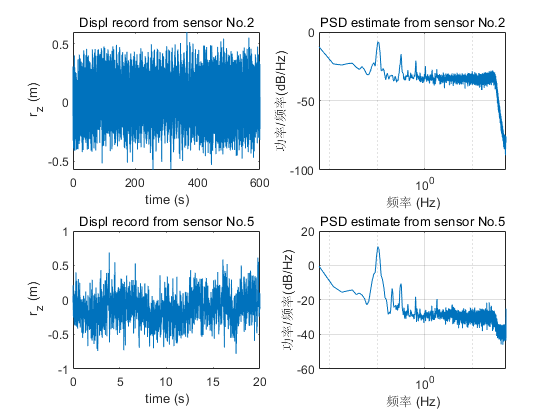

%clearvars;close all;clc;

%load('SHcenter.mat','t','rz','zetaStruct','phi','wn','posSensors','y')

fnTarget = wn/(2*pi); % transform circular frequency (rad/s) into frequency (Hz)
dt = median(diff(t)); % get time step
fs=1/dt; % get sampling freuqency
[Nyy,N]= size(rz); %Nyy is the number of sensors and N the number of time step

% Visualization of the data
clf;close all;
figure
subplot(221)
plot(t,rz(2,:))
xlim([0,600]);
xlabel('time (s)')
ylabel(' r_z (m)')
title('Displ record from sensor No.2')
subplot(222)
pwelch(rz(2,:),[],[],[],1/dt)
set(gca,'xscale','log')
title('PSD estimate from sensor No.2')
subplot(223)
plot(t,rz(5,:))
xlim([0,20]);
% xlim([0,600]);
xlabel('time (s)')
ylabel(' r_z (m)')
title('Displ record from sensor No.5')
subplot(224)
pwelch(rz(5,:),[],[],[],1/dt)
set(gcf,'color','w')
set(gca,'xscale','log')
title('PSD estimate from sensor No.5')

## Application of SSI-COV

The model order fluctuates between "Nmin" and "Nmax". The function SSICOV automatically estimates the modal parameters of the system associated with the displacement history rz. The variable "paraplot" is used to plot the stabilization diagram.

tic
[fn0,zeta0,phi0,paraPlot] = SSICOV_noToolbox(rz0,dt,'Ts',20,'Nmin',1,'Nmax',50);
toc

历时 30.407645 秒。


## Plot  the stabilization diagram

The PSD estimate of the displacement response at the position no. 2 is superposed to the the identified poles.

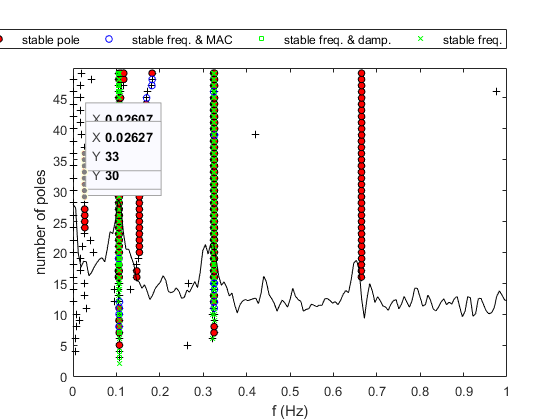

clf;close all;
[h] = plotStabDiag(paraPlot.fn,rz(3,:),fs,paraPlot.status,paraPlot.Nmin,paraPlot.Nmax);

xlim([0.0 1])
ylim([0.0 50.0])